T = readtable("2023-11-09 Surfing Sierra.txt");

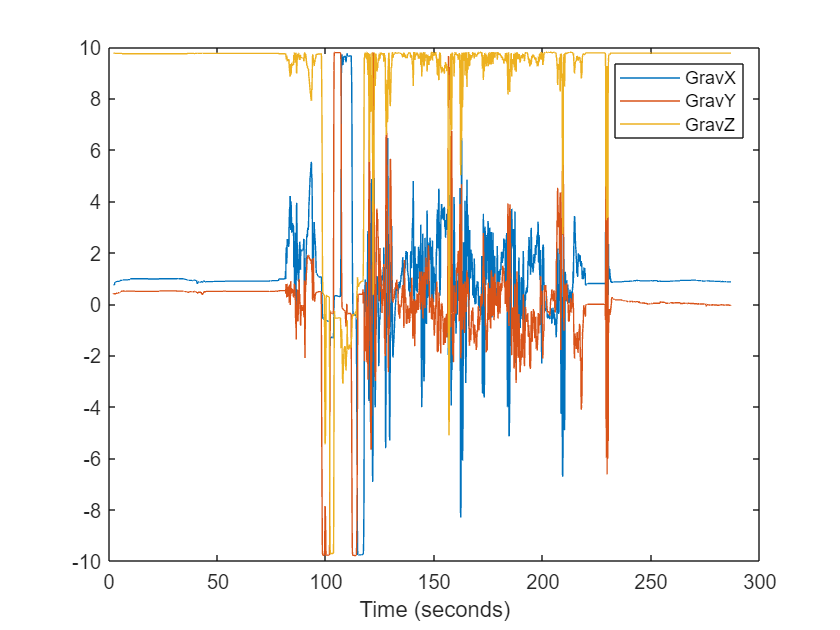

T.secs = T.t / 1000;
plot(T.secs, T.GravX);
hold on
plot(T.secs, T.GravY);
plot(T.secs, T.GravZ);
hold off
legend("GravX", "GravY", "GravZ")
xlabel("Time (seconds)");


t = T(300,:); % Just the first row

quat = [t.QuatW, t.QuatX, t.QuatX, t.QuatZ];
myrotm = quat2rotm(quat);
myrotminv = quat2rotm(quatinv(quat)); % requires Aerospace Toolbox

quatinv requires Aerospace Toolbox.

gravVec = [t.GravX, t.GravY, t.GravZ]
gravVec * inv(myrotm)
gravVec * myrotminv


quat2 = [T.QuatW, T.QuatX, T.QuatX, T.QuatZ];
size(quat2)

ans =         5661           4


myrotm2 = quat2rotm(quatinv(quat2));
size(myrotm2)

ans =            3           3        5661


grav2 = [T.GravX, T.GravY, T.GravZ];
size(grav2)
grav2 * myrotm2
